clear; clc; close all

**DEFINE SYSTEM**

% define parameters
M_p = 0.215;        % Pendulum mass                     [kg]
M_c = 1.608;        % Cart mass                         [kg]
L = 0.314;          % Effective pendulum half length    [m]
I_0 = 7.06 * 10^-3; % Pendulum moment of inertia        [kg*m^2]
R = 0.16;           % Motor terminal resistance         [ohms]
r = 0.0184;         % Pinion radius                     [m]
k_g = 3.71;         % Gearing ratio                     [unitless]
k_m = 0.0168;       % Motor BEMF constant               [V*s*rad^-1]
C = 0;              % Cart damping                      [N*s*m^-1]
g = 9.81;           % Gravitational acceleration        [m*s^2]

% pre-define matrix entries
% entry in A at pos (3,2)
A_32 = (-M_p^2 * L^2 * g)... 
    / ((M_c + M_p) * I_0 + M_c * M_p * L^2)

A_32 = -0.9521


% entry in A at pos (3,3)
A_33 = ((I_0 + M_p * L^2) * (C * R * r^2 + k_m^2*k_g^2))...
    / (((M_c + M_p) * I_0 + M_c * M_p * L^2) * R * r^2)

A_33 = 43.1573


% entry in A at pos (4,2)
A_42 = ((M_c + M_p) * M_p * L * g)...
    / ((M_c + M_p) * I_0 + M_c * M_p * L^2)

A_42 = 25.7113


% entry in A at pos (4,3)
A_43 = (-M_p * L * (C * R * r^2 + k_m^2 * k_g^2))...
    /(((M_c + M_p) * I_0 + M_c * M_p * L^2) * R * r^2)

A_43 = -103.1047


% define plant matrix A
A = [0 0 1 0;
    0 0 0 1;
    0 A_32 A_33 0;
    0 A_42 A_43 0]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -0.9521   43.1573         0
         0   25.7113 -103.1047         0



% check to see that matrix entries are correct
assert(A(3,2) == A_32, 'matrix A positioning wrong')

% entry in B at pos (3,1)
B_31 = (-(I_0 + M_p * L^2) * k_m * k_g)...
    / (((M_c + M_p) * I_0 + M_c * M_p * L^2) * R * r)

B_31 = -12.7406

% entry in B at pos (4,1)
B_41 = (M_p * L * k_m * k_g)...
    / (((M_c + M_p) * I_0 + M_c * M_p * L^2) * R * r)

B_41 = 30.4378


% define input matrix B
B = [0;
    0;
    B_31;
    B_41]

B =          0
         0
  -12.7406
   30.4378



% check to see that matrix entries are correct
assert(B(3,1) == B_31, 'matrix B positioning wrong')

% define sensor matrix C
C = eye(size(A))

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



% define whatever matrix D is
D = 0

D = 0


sys = ss(A, B, C, D)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3        0  -0.9521    43.16        0
   x4        0    25.71   -103.1        0
 
  B = 
           u1
   x1       0
   x2       0
   x3  -12.74
   x4   30.44
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



**CONTROL**

% set system poles
poles = [-5+1i -5-1i -10+2i -10-2i];

K = place(A, B, poles)

K =     9.0558   15.4770    1.8371    3.1725



ACL = (A - B*K)

ACL =          0         0    1.0000         0
         0         0         0    1.0000
  115.3754  196.2339   66.5627   40.4189
 -275.6371 -445.3754 -159.0214  -96.5627



sys = ss(ACL, B, C, D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3   115.4   196.2   66.56   40.42
   x4  -275.6  -445.4    -159  -96.56
 
  B = 
           u1
   x1       0
   x2       0
   x3  -12.74
   x4   30.44
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.




Q = diag([1, 1, 100, 100]);
R = 1;

K = lqr(sys, Q, R)

K =     0.0550   53.2015    9.8181   14.1688


**RESPONSE**

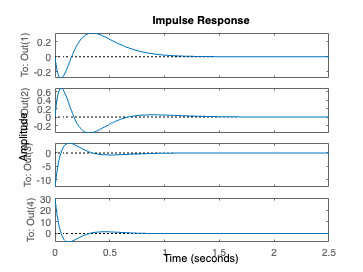

% scale input B to match 0.1m inputs in lab

% sys.B = 10*sys.B;

figure
impulse_plot = impulseplot(sys);

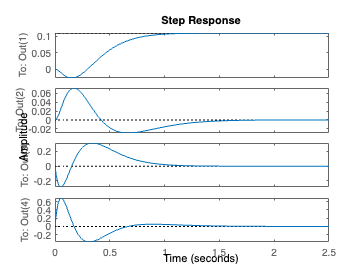


figure
step_plot = stepplot(sys);

e = step(sys)

e =          0         0         0         0
   -0.0005    0.0012   -0.1020    0.2438
   -0.0018    0.0043   -0.1766    0.4226
   -0.0037    0.0088   -0.2283    0.5474
   -0.0059    0.0142   -0.2609    0.6277
   -0.0084    0.0202   -0.2777    0.6716
   -0.0110    0.0265   -0.2816    0.6860
   -0.0136    0.0328   -0.2752    0.6771
   -0.0161    0.0389   -0.2605    0.6498
   -0.0184    0.0447   -0.2394    0.6085


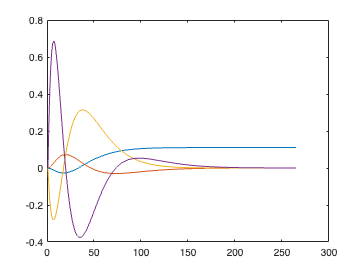

plot(e)